### Comparing our measurements of lower lip fluorescence to other published data on oral mucosal tissue 

%{
cd /Users/joyce/Github/isetcam; addpath(genpath(pwd));
cd /users/joyce/Github/oraleye/; addpath(genpath(pwd));
cd /users/joyce/Github/isetfluorescence/; addpath(genpath(pwd));
cd /users/joyce/Github/oe_tongue_lip/; addpath(genpath(pwd));
%}

ieInit;
wave = 500:585;

de Veld, D. C., Skurichina, M., Witjes, M. J., Duin, R. P., Sterenborg, D. J., Star, W. M., & Roodenburg, J. L. (2003).  Autofluorescence characteristics of healthy oral mucosa at different anatomical sites. Lasers in Surgery and Medicine: The Official Journal of the American Society for Laser Medicine and Surgery, 32(5), 367-376

Figure 4, "Mean autofluorescence spectra of healthy oral mucosa obtained at four representative locations, excitation wavelength 405 nm" , cheek mucosa and the dorsal side of the tongue

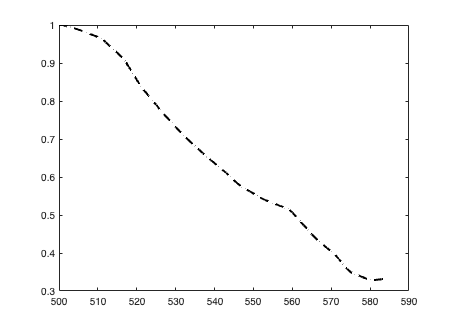

mucosa = ieReadSpectra('CheekVeld2003.mat',wave); 
ieNewGraphWin; plot(wave,mucosa/max(mucosa(:)),'k--','lineWidth',2); hold on;

Betz, C. S., Mehlmann, M., Rick, K., Stepp, H., Grevers, G., Baumgartner, R., & Leunig, A. (1999). Autofluorescence imaging and spectroscopy of normal and malignant mucosa in patients with head and neck cancer, Lasers in Surgery and Medicine: The Official Journal of the American Society for Laser Medicine and Surgery, 25(4), 323-334.

Figure 3 Averaged autofluorescence spectra from 36 patients for "healthy tissue" adjacent to malignant tissue.  I only digitized the data for healthy tissue

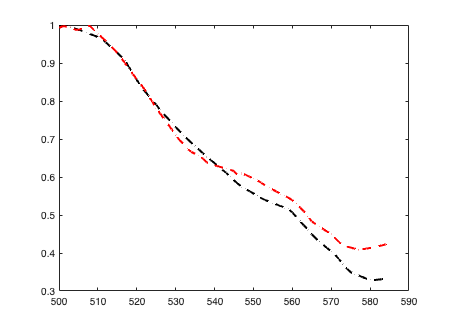

mucosa = ieReadSpectra('Betz1999.mat',wave);
plot(wave,mucosa/max(mucosa(:)),'r--','lineWidth',2); 

Van Staveren, H. J., Van Veen, R. L. P., Speelman, O. C., Witjes, M. J. H., Star, W. M., & Roodenburg, J. L. N. (2000). Classification of clinical autofluorescence spectra of oral leukoplakia using an artificial neural network: a pilot study.  Oral oncology, 36(3), 286-293.

data from Figure 3 as example of oral mucosa measured with probe and **420 excitation**, surrounding "normal" tissue ...' 

Autofluorescence spectra were measured from 465 to 650 nm (475-nm long wavelength pass filter

based on one patient 

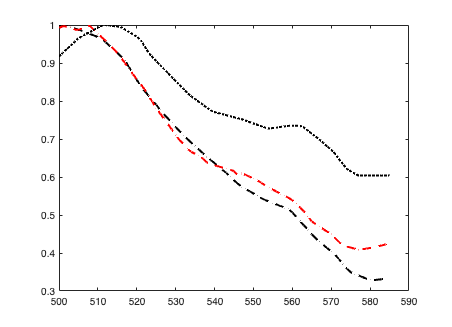

mucosa = ieReadSpectra('VanStaveren2000.mat',wave);
plot(wave,mucosa/max(mucosa(:)),'k:','lineWidth',2);

Roy, K., Bottrill, I., Ingrams, D. R., Pankratov, M. M., Rebeiz, E. E., Woo, P., & Feld, M. S. (1995, May) Diagnostic fluorescence spectroscopy of oral mucosa. In Lasers in Surgery: Advanced Characterization, Therapeutics, and Systems V (Vol. 2395, pp. 135-142). SPIE.

**extracted tissue** from "normal" and from "lesions" and measured EEM to find best excitation light

only 20 samples, 8 "normal"- 

" The most significant differences were obtained when an excitation wavelength of 410 nm was used. Almost all the abnormal specimens showed a prominent emission peak at 635 nm with increased red fluorescence"  None of the sites included the dorsal tongue

It is important to note that many papers (including paper by Venugopal cited below) make assertions that cannot be supported about why oral lesions have reduced fluorescence or increased porphyrins. We ignore this, and only use their data for "**typical normal oral mucosa emission**") **with 410 excitation light **(Figure 6 in this paper) -** one tissue sample?  perhaps we don't use this.** 

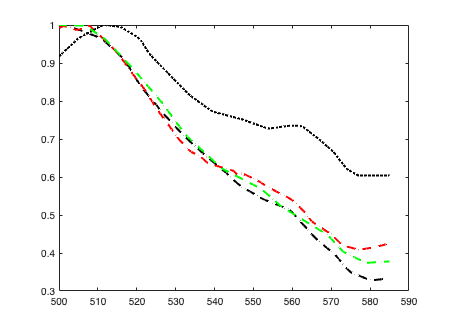

mucosa = ieReadSpectra('Roy1995.mat',wave);
plot(wave,mucosa/max(mucosa(:)),'g--','lineWidth',2); ; 

Venugopal, C., Nazeer, S. S., Balan, A., & Jayasree, R. S. (2013). Autofluorescence spectroscopy augmented by multivariate analysis as a potential noninvasive tool for early diagnosis of oral cavity disorders. *Photomedicine and laser surgery*, *31*(12), 605-612.

This is not a great paper (see unsupported assertions the authors make about why there is reduced fluorescence in oral leukoplakia in buccal mucosa of patients). Ignoring that, they do have measurements of fluorescence in normal buccal mucosa tissue.

"AF spectra were acquired from affected sites of patients and from right and left buccal mucosa of normal volunteers....The** excitation wavelength of 410 nm** was selected" 

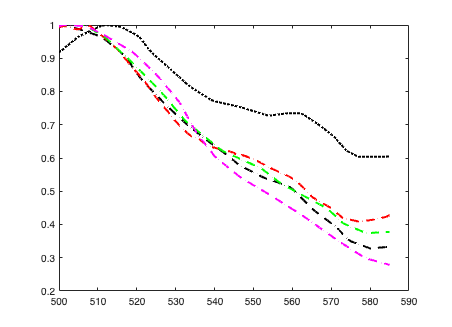

mucosa = ieReadSpectra('Venugopal2013.mat',wave);
plot(wave,mucosa/max(mucosa(:)),'m--','lineWidth',2); 

Mallia, R. J., Thomas, S. S., Mathews, A., Kumar R, R., Sebastian, P., Madhavan, J., & Subhash, N. (2008). Laser‐induced autofluorescence spectral ratio reference standard for early discrimination of oral cancer. *Cancer*, *112*(7), 1503-1512.

" LIAF emission spectra from oral mucosa were recorded in the 420–720 nm spectral range on a miniature fiberoptic spectrometer from 14 anatomical sites of 35 healthy volunteers and 91 sites of 44 patients, with **excitation at 404 nm** from a diode laser."

Figure 3: "14 different anatomical sites of the oral cavity of healthy volunteers" mean LIAF (Laser-induced autofluorescence)

vermilion border of the lip, the dorsal and the lateral sides of tongue showed porphyrins

another flawed paper arguing that porphryins in oral muccosal tissue (buccal, floor of mouth, alveolus, inner lip)  is diagnostic of cancer ... consistent with the theory that porphyrins tend to accumulate in lesions ...

nonetheless, they have measurements from different sites in healthy volunteers .. but normalized and averaged over 15 measurements in 35 volunteers

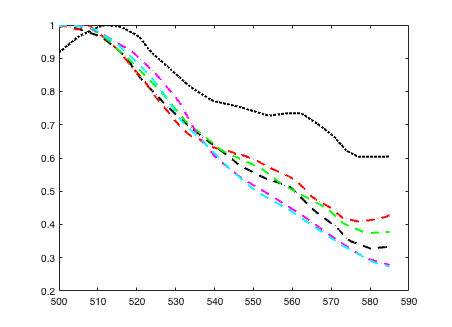

mucosa = ieReadSpectra('MucosaMallia2008.mat',wave);
plot(wave,mucosa/max(mucosa(:)),'c--','lineWidth',2); 

## Read a couple of raw data sets

This is the database of raw measurements.

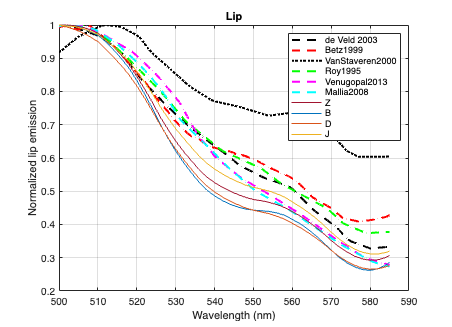

[T,dataDir] = oeDatabaseCreate;

files405Z = ieTableGet(T,'subject','Z','substrate','lip','e wave',405,'e level',980,'return','files');
files405B = ieTableGet(T,'subject','B','substrate','lip','e wave',405,'e level',980,'return','files');
files405D = ieTableGet(T,'subject','D','substrate','lip','e wave',405,'e level',980,'return','files');
files405J = ieTableGet(T,'subject','J','substrate','lip','e wave',405,'e level',980,'return','files');
lipFiles = cat(1,files405Z,files405B,files405D,files405J);

lipData = zeros(numel(wave),numel(lipFiles));

for ii=1:numel(lipFiles)
    data = ieReadSpectra(fullfile(dataDir,lipFiles{ii}),wave); 
    lipData (:,ii) = data(:);
    plot(wave,data/max(data(:))); hold on;
end
legend({'de Veld 2003','Betz1999','VanStaveren2000','Roy1995','Venugopal2013','Mallia2008','Z','B','D','J'});
title('Lip');
xlabel('Wavelength (nm)'); ylabel('Normalized lip emission'); grid on;